## GUIÃO 3.1

## 1. 

## **Um aluno do primeiro ano de um curso de Engenharia tem duas aulas Teorico-Práticas de uma Unidade Curricular X todas as semanas, às 9:00, nas quartas e sextas-feiras.**

## **Todos os dias em que o aluno tem aulas desta UC, ele decide se vai à aula ou não da seguinte forma: se ele esteve presente na aula anterior, a probabilidade de ir à aula é de 70%; se ele faltou à aula anterior, a probabilidade de ir é de 80%.**

## (a) Se estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte? Sugestao: Comece por definir a matriz de transição de estados e o vetor estado correspondentes. 

Mp = [0.2 0.8 ; 0.3 0.7];

%   F       P
%F  0.2     0.8
%P  0.3     0.7
a = Mp^2;
disp(a(2,2))

    0.7300



## (b) Se não estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte?

disp(a(1,2))

    0.7200



## (c) Sabendo que esteve presente na primeira aula, qual a probabilidade de estar na ultima aula, assumindo que o semestre tem exactamente 15 semanas de aulas e nao existem feriados?



a = Mp^29;   %2 aulas * 15 semanas = 30 -> 30- 1 sexta feira= 29 aulas
disp(a(2,2))

    0.7273



## (d) Represente num grafico a probabilidade de faltar a cada uma das 30 aulas, assumindo que a probabilidade de estar presente na primeira aula e de 85%.

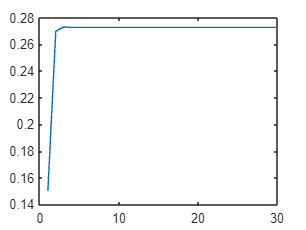

probs = ones(1,30);
probs(1) = 0.15;
x = [1 0]';

for i=2:30
    p = Mp^i*x;
    probs(i) = p(2,1);
end
plot(probs);